# Implementing the Chaos Game

[⇦ Overview](matlab: run("OpenOverview.m"))

Using the branching and looping controls from [Branches](matlab:open('./Branches')) and [Loops](matlab:open('./Loops.mlx')), this script will walk you through building out an implementation of the chaos game from bare bones to the ability to generate intricate designs automatically. 

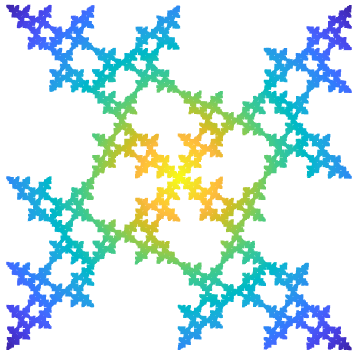         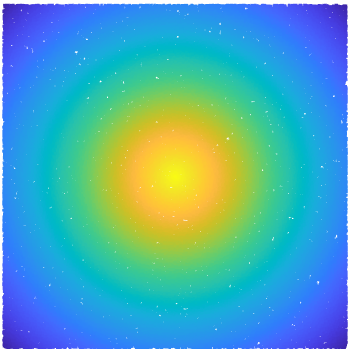         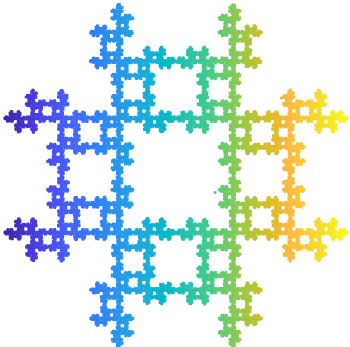

This project will increase your familiarity with branches and loops in a context where their utility is key to observing the desired results.

**Before you get started:**

This live script is intended to be used with the code visible and output inline. On **View** tab of the MATLAB toolstrip, in the **View** section, select **Output Inline**. Alternately, select **Output inline **using the icon   at the top right of the Live Editor pane.

 Interacting with this live script will build some familiarity with MATLAB, as concepts and commands are introduced together, but some familiarity with the Live Editor environment was introduced in [Introduction.mlx](matlab:open('./Introduction.mlx')). A brief summary of the tools, tips, and suggestions from each script is gathered in [Collected Pro Tips](matlab:open('./CollectedProTips.mlx')). This script will use content that you are not expected to understand yet, but you are encouraged to practice your reference skills and explore the documentation to continue learning beyond what is required to complete this project.

   For an optimal experience, follow the instructions and steps in the given sequence. Proceed to a new section only after completing the preceding one, including running all code blocks.

## **Application of Branches and Loops: Chaos Game**

The chaos game is a set of rules that can be applied to many different polygons with varying results. This implementation investigates the chaos game on a square. Beginning at a randomly selected point, at each iteration of the game a new point is selected that is the average of the current point and a randomly selected vertex of the square. Eventually, it will be convenient to be able to easily identify and compare vertices of the square using the map presented:

chaosSquareMap

** Exercise 1**.

Write a switch statement that switches on the variable `newCorner` with the cases `1, 2, 3, `and` 4`. It should set the value of `newCoords` to the appropriate vector in each case.

newCorner = randi(4,1)
newCoords = [-1 -1];

% Write the switch statement here.
% Run this section to test that the coordinates in newCoords that you get out 
% are what you expect based on the value of newCorner and NOT [-1 -1]

newCoords

**Note:** Exercise 1 is required in the code below.

#### Starting the Chaos Game

Moving on, to start the chaos game, you need to select a starting point. To make the case that the starting point does not impact the eventual results, the code below chooses that starting point randomly. The line `startingPoint = rand([1 2])` has been left unsuppressed so you can track the initial value, but feel free to add a semicolon to suppress the output whenever you have convinced yourself that the code works as expected. In fact, it doesn't matter if your random starting point is inside the square or not, but it is a bit easier to visualize what is going on if the initial point is visible. Run the code below to start a chaos game. 

chaosSquare                   % Draw a unit square of a standard size for future reference
hold on                       % Continue drawing on this figure
startingPoint = rand([1 2])   % Generate a random starting point in the square

% Graph and label the starting point. Note the coordinate shift by 0.02 in
% the x direction for readibility. 
s = scatter(startingPoint(1),startingPoint(2),'o','filled');
text(s.XData + 0.02,s.YData,"Starting Point")
hold off

#### Adding New Points

The next step is to randomly select one of the vertices of the square. To be able to run this code, you need to paste in your solution to Exercise 1 as instructed in the comments. Then run the code at least once before moving on to Exercise 2. 

hold on
%% Code for Exercise 2 goes here

%%

newCorner = randi(4,1);
%% Paste the switch statment from Exercise 1 here

%%     

% In the annotation space coordinates, the corners of the square have 
% x = .3 or x = .735 and y = .23 or y = .81. Shift the coordinates to
% account for the transformation by (x-coords)*(.735-.3)+.3 and
% (y-coords)*(.81-.23)+.23
annotation("arrow",[s.XData(end) (s.XData(end)+newCoords(1))/2]*.435+.3, ...
    [s.YData(end) (s.YData(end)+newCoords(2))/2]*.58+.23)
% Add the new point to the scatter plot
s.XData = [s.XData (s.XData(end)+newCoords(1))/2];
s.YData = [s.YData (s.YData(end)+newCoords(2))/2];
pause(.4)

%% Code for Exercise 2 goes here as well

%% 
hold off

** Exercise 2**.

The chaos game doesn't stop with one step, however. Add a `for` loop around the code above to continue the game for at least 8 steps. There are comments in the code that give you hints about where your `for` loop should go. 

This is all fine, but the real reason to play the chaos game with a computer rather than on paper is the ability to repeat many times so you can determine if there are interesting results. Run the code in the file `chaosGame.m` below. 

tic            
chaosGame
toc            

 **Reflect**.

- What do you think the `tic` and `toc` commands do? How would you find out what these commands do?

- Is there a pattern in this image? Why or why not?

#### Modifying chaosGame.m

Open the file [`chaosGame.m`](matlab:open('./chaosGame.m')) . This will open the file in a new tab for you to read and edit. You do not need to change Lines 1-20, but you should read them to give yourself context for the rest of the script. It is extremely common to begin solving a coding problem by starting with example code (or snippets of sample code) written previously, likely even by other people, that is similar to what you are trying to do. Your challenge is to understand how to change or build upon what already exists to solve the problem you are interested in now. 

** Exercise 3**.

The chaos game renders very slowly because every time it solves for a new point it stops to draw it. This may be deterring you from running the game far enough to formulate an idea of the final picture. 

a) Edit `chaosGame.m` to make the code run faster by adding a conditional to the `drawnow` code on line 48 to reduce the number of times the code will pause to draw the image. The condition `mod(k,ceil(numPts/50)) == 0` works well. Should you use an `if/then` or a `switch` or a `for` loop or a `while` loop for this change?

b) Use the documentation to determine what the functions `mod` and `ceil` do and explain what this condition achieves. 

c) Time how long it takes to render 5000 points. 

d) Do you see a pattern now? Why or why not? You may want to go up to 25,000 or 50,000 points. 

 **Reflect**

- Is it easier to write your own code or modify code that someone else has written? Does it matter what you are trying to change?

- Is it necessary to understand every line of code in a file before you start to change things? Why or why not?

- Is it necessary to understand every line of code that you write? Why or why not?

** Exercise 4**.

The basic chaos game can move towards any vertex. If you add a condition on the possible next vertex, what does that do to the result?

Options: 

- Do not repeat vertices. That is, whenever `newVertex == oldVertex`, select a new randomized `newVertex`

- Do not move diagonally. That is, whenever `mod`(`newVertex,4) == mod(oldVertex + 2,4)`, select a new randomized `newVertex`

- Do not move clockwise. That is, whenever `mod(newVertex,4) == mod(oldVertex + 1,4)`, select a new randomized `newVertex`

- Do not move counterclockwise. That is, whenever `mod(newVertex,4) == mod(oldVertex - 1,4)`, select a new randomized `newVertex`

a) By working through each possible option for `newVertex = rand(4,1)`, explain why the code

does not correctly implement the restriction described in Option 1. 

b) Using a `while` loop, implement one of these options and then save and run `chaosGame.m` for at least 5,000 iterations. What patterns do you see? Can you explain why you see them?

chaosGame

** Exercise 5**

In Exercise 4, one problem with randomly selecting the initial point becomes clear because the first few points may not fit in with the rest. With judicious copy-pasting from inside the existing loop,

add a new loop to create and throw away at least the first 20 points. Then run your code for 25,000 iterations to generate a clear image.

chaosGame

  **Try**. Predict what happens if you insert the following code after 

`newPoint = (newCoords-startingPoint)/2 + startingPoint;` 

in `chaosGame.m.`

Then test your predictions by updating and running the code.

 **Reflect**

- In Exercise 3, you timed the running of the code to allow a quantitative efficiency comparison. Can you estimate how much time it would take to run the original code with 25,000 points? Why do you think so?

- In Exercise 4, why did you need to use, e.g., `mod(newVertex,4) == mod(oldVertex + 2,4)` rather than just checking if `newVertex == oldVertex + 2`?

- In Exercise 4, what would happen if you used a `for` loop instead of a `while` loop? 

- Can you think of other instances where there are transient conditions you might want to ignore, as in Exercise 5?

- Given the work you have done, can you predict what the results will be for one of the other options in Exercise 4? How much work is it to modify your code to test your prediction

- In Exercise 1, you wrote a switch statement so that there was a clear mapping from the named Corner 1, Corner 2, etc to the coordinates of the points: (0,0), (1,0), etc. If you wish to avoid switches, you could randomly generate the coordinates using

            How would you have to rewrite the rest of the code in `chaosGame.m` to implement the options in Exercise 4?

## File Formats - Sharing Results

While it can happen that code is written simply to solve a question of interest to the coder, frequently other people may be interested in the results as well. In this case, there is a beautiful image that you may want to share with a friend or use as decoration. To export an image, you will need to choose what file format to use. There are many different image file formats, each of which corresponds to a different method of encoding the information to allow another computer to recreate and display the image of interest. The *file extension* commonly indicates the encoding used for the file. Here is a table that contains several common data formats you may have encountered. 

load("fileformats.mat")
FileFormatsTable
% This file is .mlx. What is that?
% FileFormatsTable(find(FileFormatsTable.FileExtensions == ".mlx"),:)
FileFormatsTable(FileFormatsTable.FileExtensions == ".mlx",:)

  **Try**. Modify the code above to locate and display the information about .avi files rather than .mlx files.

 **Reflect**

- What type of pattern recognition lets you modify the table search code from looking for `.mlx` file types to looking for `.avi` file types? Do you need to understand what each component of the code does in order to find what you want?

- If you did need to understand the whole line of code, where would you start looking?

** Exercise 6**.

    a) Pick your favorite image that you created using `chaosGame.m` and export it to a png file using the commands: 

        Read the documentation and explain what the `gca` argument is doing. You can change the name `MyFilename` as you wish. 

% Exercise 6a code goes here

    b) Create a text file called `fileInfo.txt` from the `FileFormatsTable` table. Read the documentation to build the appropriate command. 

doc write-to-delimited-data-files
% Exercise 6b code goes here



[⇦ Overview](matlab: run("OpenOverview.m"))

## Helper Functions

#### Image generation code

function chaosSquare
% This function generates the annotated image of the square board for the
% Chaos Game where each corner is labeled with only its integer label

figure
rectangle("Position",[0 0 1 1],"Curvature",[0 0])
xlim([-0.2,1.2])
ylim([-0.2,1.2])
text(-0.05,-0.05,"1")
text(-0.05,1.05,"2")
text(1.02,1.05,"3")
text(1.02,-0.05,"4")

% This figure is prettier when drawn with equal measurements along both the
% x and y axes, but without the axes showing
axis square off
end


function chaosSquareMap
% This function generates the annotated image of the square board for the
% Chaos Game where each corner is labeled with both its integer label and
% its coordinate values for reference

figure
rectangle("Position",[0 0 1 1],"Curvature",[0 0])

% Label each corner with its corresponding value
text(-0.05,-0.05,"1")
text(-0.05,1.05,"2")
text(1.02,1.05,"3")
text(1.02,-0.05,"4")

% Label each corner with its corresponding coordinates
text(.02,.05,"(0,0)")
text(.02,.97,"(0,1)")
text(.87,.97,"(1,1)")
text(.87,.05,"(1,0)")

% Set the range and domain for the viewing window
xlim([-0.2,1.2])
ylim([-0.2,1.2])

% This figure is prettier when drawn with equal measurements along both the
% x and y axes, but without the axes showing
axis square off
end